# **Apoyo en el desarrollo del Proyecto de Grado MIACON**

[MÓDULO 2: Identificación y control de una planta de primer orden](https://sites.google.com/view/miacon-proyectodegrado/gu%C3%ADas-de-laboratorio/m%C3%B3dulo-2-identificaci%C3%B3n-y-control-de-una-planta-de-primer-orden)

- `Hecho por:`` Diego Andrés García Díaz.`

- `Código:`` 2195533.`

- `Fecha:`` 26/09/2025.`

- `Asignatura:`` Control II (Adelanto de Nota).`

## Módelo para un Sitema Térmico (Primer Orden)

### $G_P \left(\mathcal{s}\right)=\frac{K_p }{T_{\textrm{p1}} \cdot \mathcal{s}+1}\cdot e^{-T_d \cdot \mathcal{s}}$;

### $G_P \left(\mathcal{s}\right)=\textrm{Actuador}+\textrm{Planta}+\textrm{Sensor}$;

### $K=K_p =\textrm{Ganancia}$; 

$K=\frac{\Delta Y\;\left(\textrm{salida}\right)}{\Delta U\;\left(\textrm{entrada}\right)}$**;**

### ${T=\;T}_{\textrm{p1}} =\textrm{Constante}\;\textrm{de}\;\textrm{tiempo}$; 

$T=\frac{3}{2}\left(t_2 -t_1 \right)$**;**

### ${L=\;T}_d =\textrm{Tiempo}\;\textrm{muerto}\;\left(\textrm{Delay}\right)$ ;


$$L=t_2 -T$$


## Modelo identificado siguiendo las instrucciones de la página web:

## 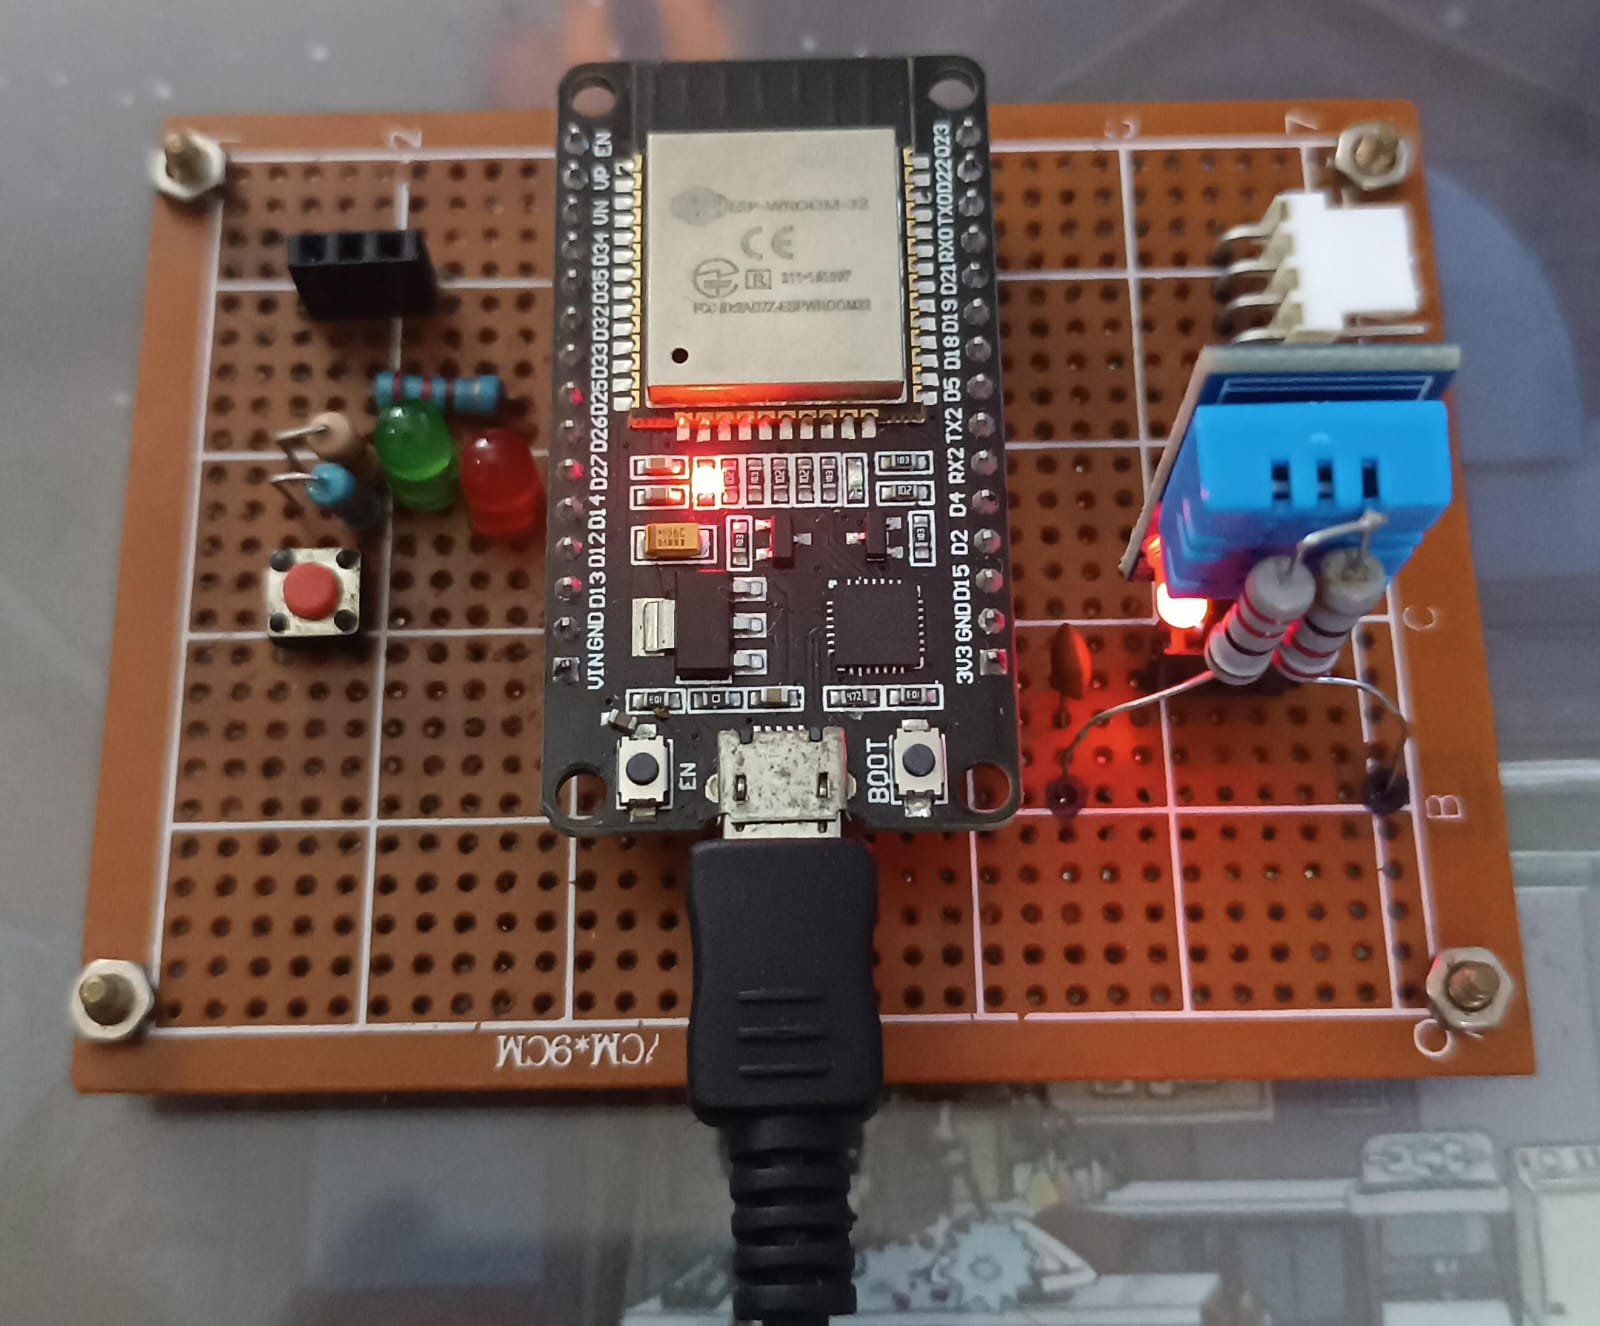

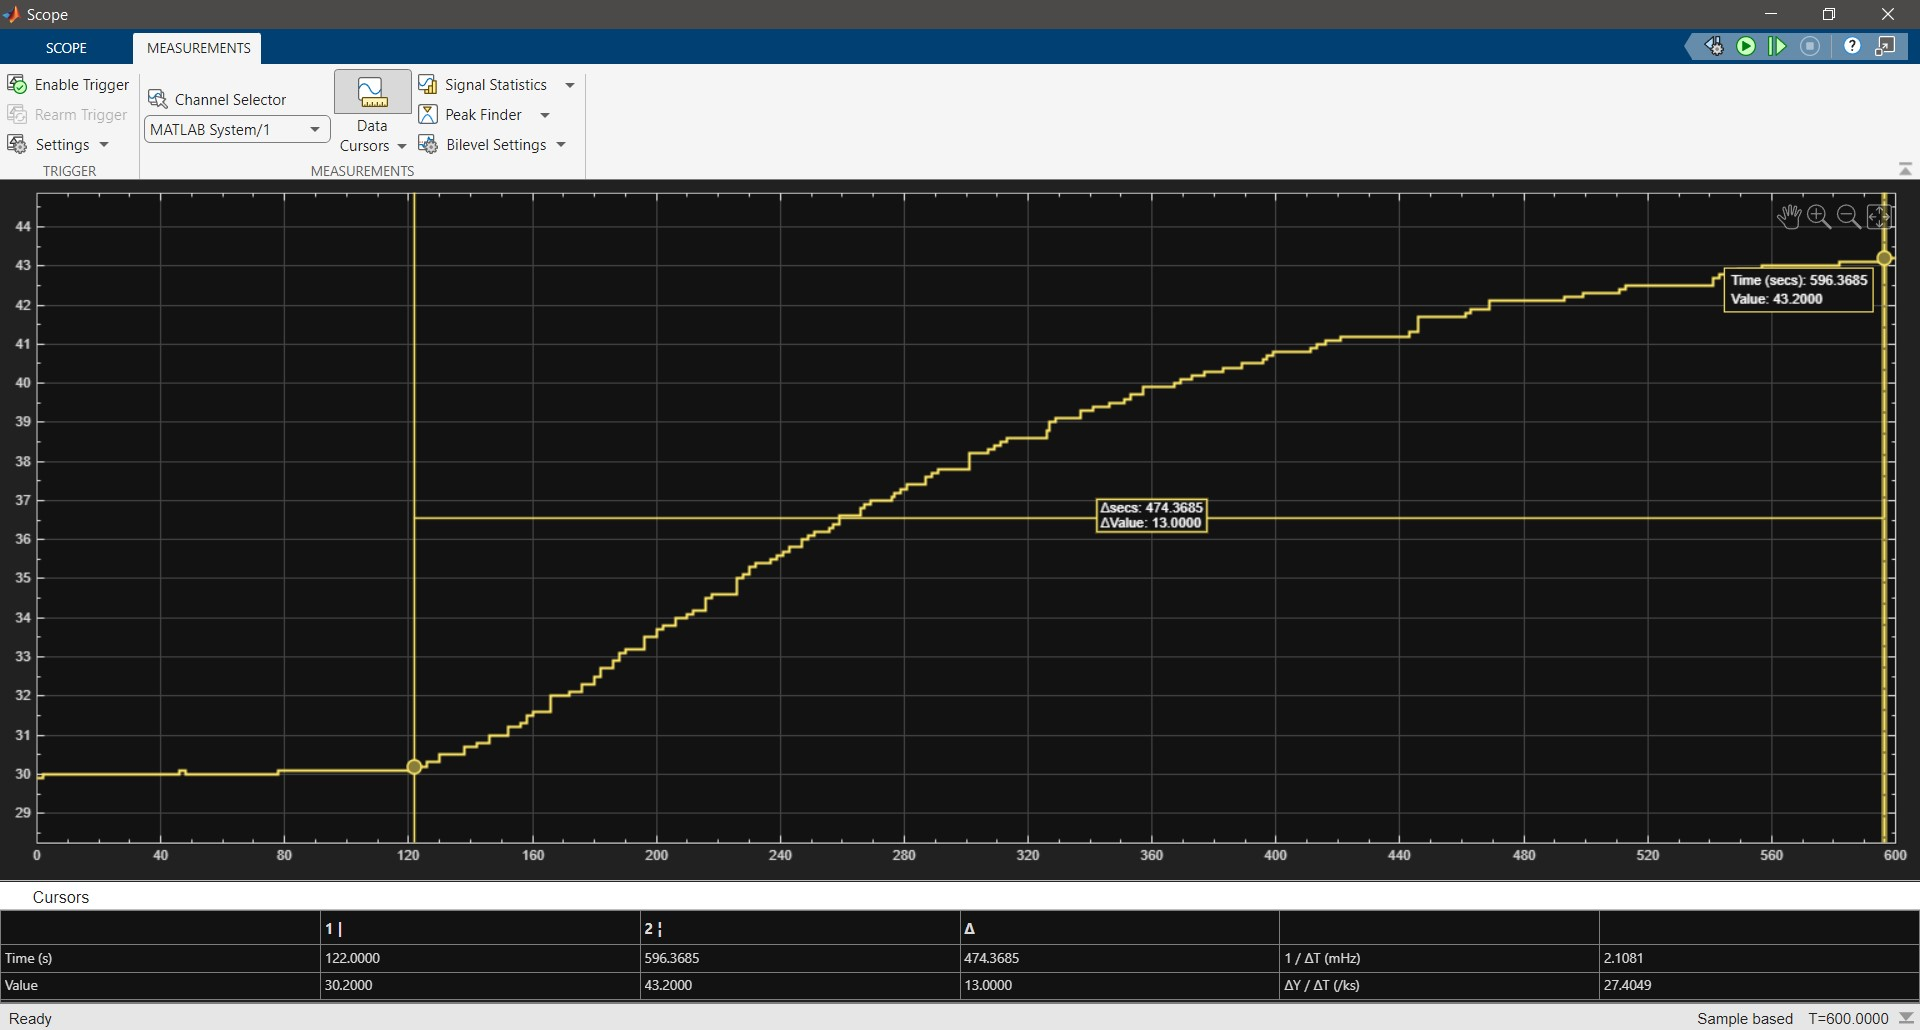

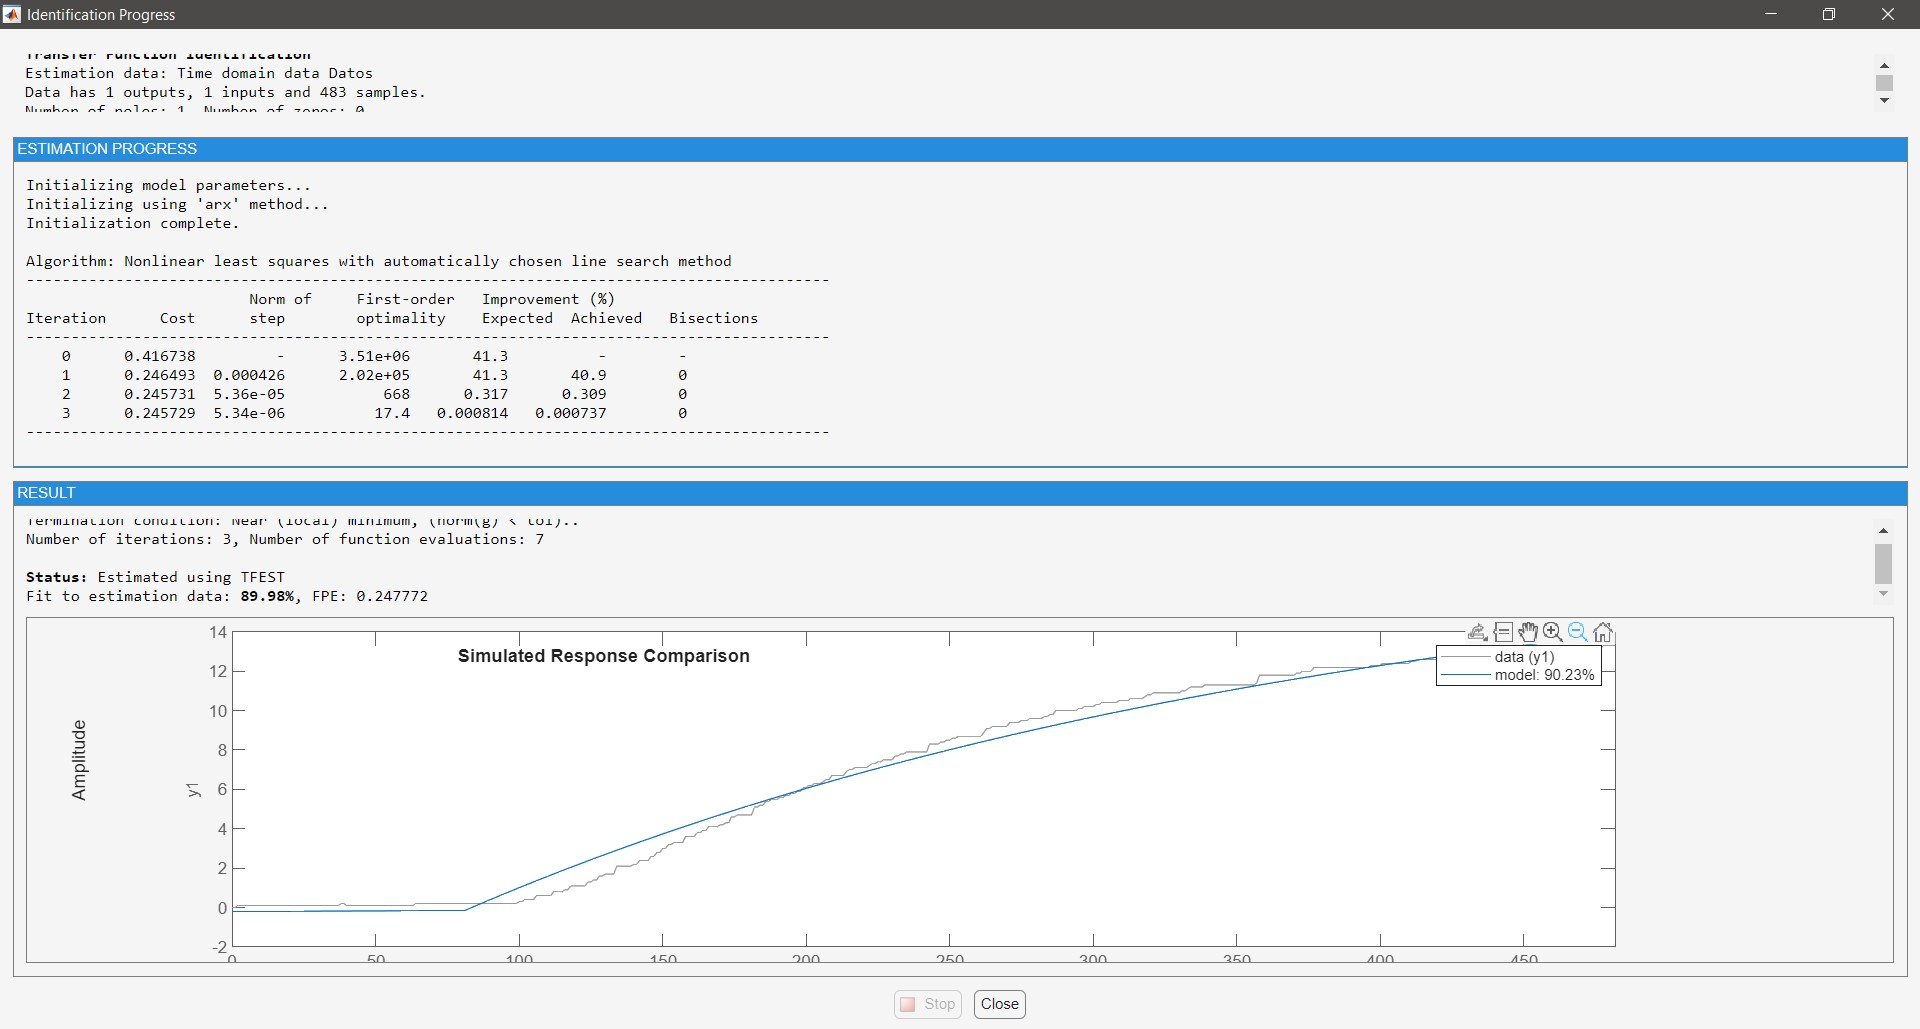

## 
$${\textrm{P1D}\;\;\;\to \;\;\;G}_{P_1 } \left(\mathcal{s}\right)=P\left(\mathcal{s}\right)=\frac{0\ldotp 11864}{170\ldotp 65\cdot \mathcal{s}+1}\cdot e^{-30\cdot \mathcal{s}}$$


### `Ajuste de 90.23% > 80%`

### **Validación en Simulink:**

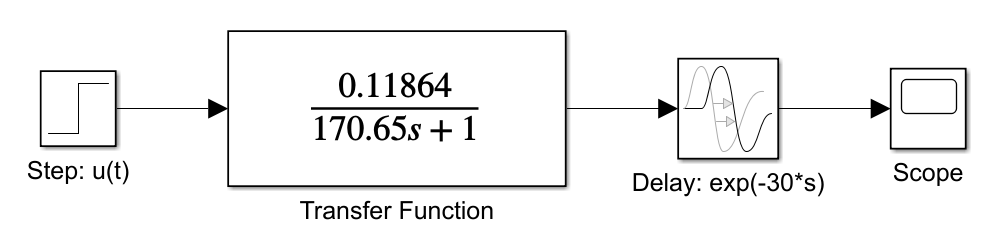

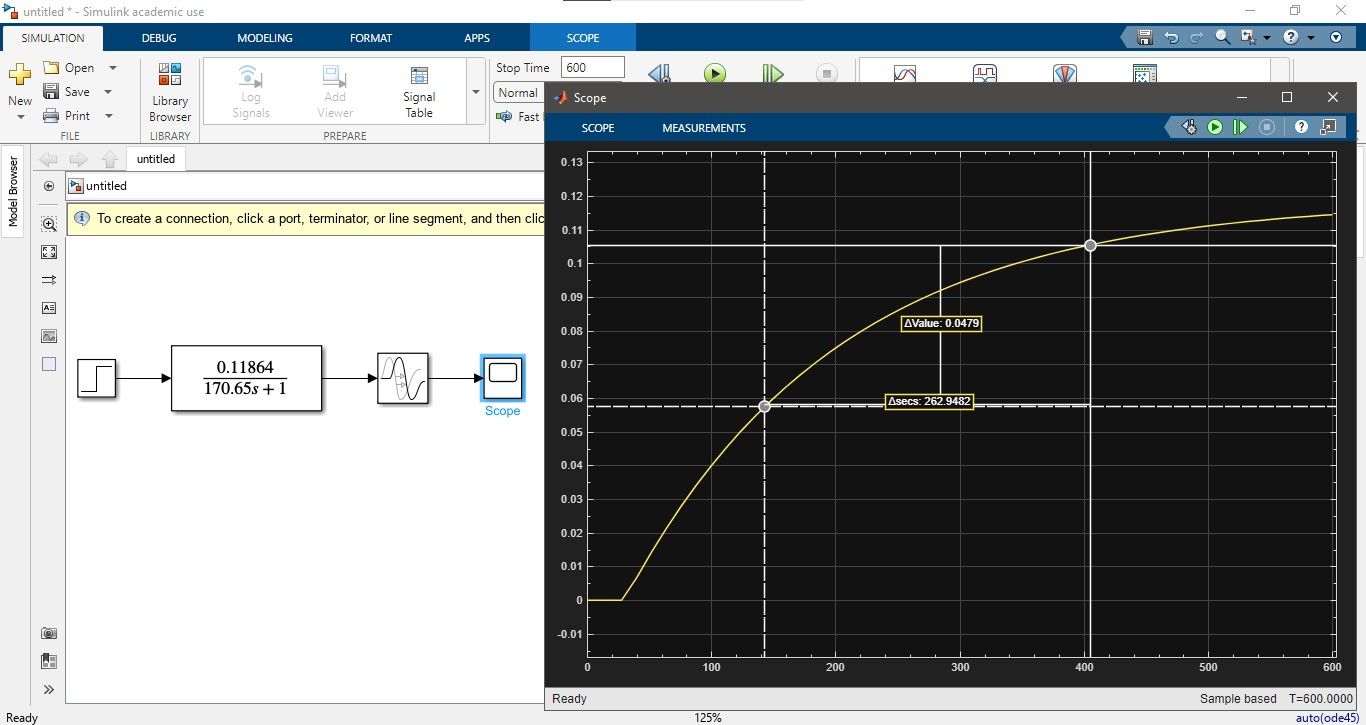

## 
$$G_P \left(\mathcal{s}\right)=\frac{0\ldotp 1144}{158\ldotp 7423\cdot \mathcal{s}+1}\cdot e^{-31\ldotp 7485\cdot \mathcal{s}}$$


#### $t_1 =L+\frac{1}{3}\cdot T=84\ldotp 6626\;\left\lbrack s\right\rbrack$**; **$t_2 =L+T=190\ldotp 4908\;\left\lbrack s\right\rbrack$** ;**

#### $\textrm{Ganancia}\;\;\to \;\;\;K=\frac{\Delta Y\;\left(\textrm{salida}\right)}{\Delta U\;\left(\textrm{entrada}\right)}=0\ldotp 1144$**; **

#### $\textrm{Constante}\;\textrm{de}\;\textrm{tiempo}\;\;\to \;\;\;T=\frac{3}{2}\left(t_2 -t_1 \right)=158\ldotp 7423\;\left\lbrack s\right\rbrack$**; **

#### 
$$\textrm{Retardo}\;\;\to \;\;\;L=t_2 -T=31\ldotp 7485\;\left\lbrack s\right\rbrack$$


### **A continuación se presenta el desarrollo para el respectivo deseño de los controladores P, PI, PD y PID:**

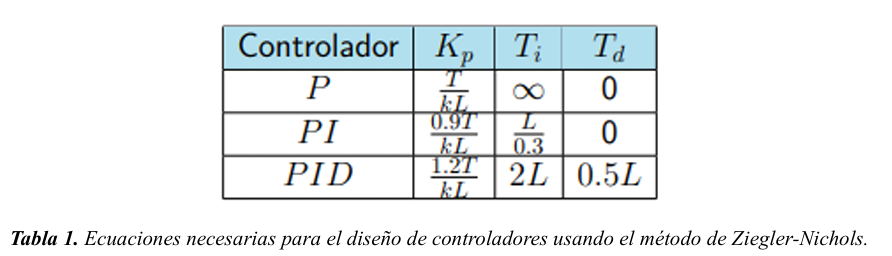

En este caso se definieron las constantes para un **controlador PI**.

#### 
$$\mathrm{Funciona}\;\mathrm{mejor}\;\mathrm{cuando}\;\;\to \;\;\;0\ldotp 1<\frac{L}{T}<0\ldotp 6$$


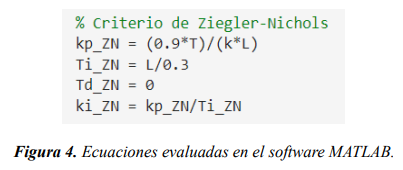

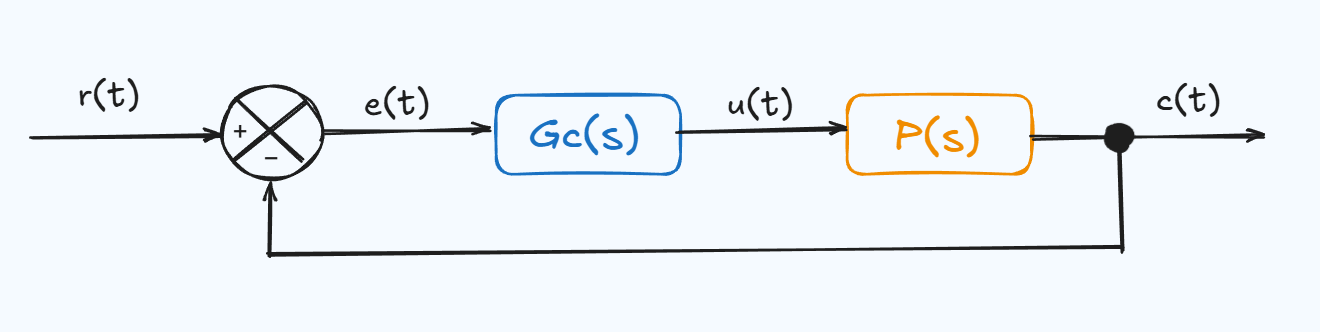

El siguiente procedimiento corresponde al cálculo del **controlador proporcional (P)**:

#### 
$$G_{\textrm{LC}} \left(\mathcal{s}\right)=\frac{C\left(\mathcal{s}\right)}{R\left(\mathcal{s}\right)}=\frac{G_C \left(\mathcal{s}\right)\cdot P\left(\mathcal{s}\right)}{1+G_C \left(\mathcal{s}\right)\cdot P\left(\mathcal{s}\right)}\approx \frac{\omega_n^2 }{{\mathcal{s}}^2 +2\cdot \zeta \cdot \omega_n \cdot \mathcal{s}+\omega_n^2 }$$



$$G_C \left(\mathcal{s}\right)=\frac{U\left(\mathcal{s}\right)}{E\left(\mathcal{s}\right)}=K\frac{\left(\mathcal{s}+z_1 \right)\cdot \left(\mathcal{s}+z_2 \right)\;\ldotp \ldotp \ldotp \;\left(\mathcal{s}+z_m \right)}{\left(\mathcal{s}+p_1 \right)\cdot \left(\mathcal{s}+p_2 \right)\;\ldotp \ldotp \ldotp \;\left(\mathcal{s}+p_n \right)}\;\;\to \;\;\mathrm{Función}\;\mathrm{de}\;\mathrm{Transferencia}\;\mathrm{del}\;\mathrm{Controlador}\;\mathrm{Generalizada}$$



$$P\left(\mathcal{s}\right)=\frac{N\left(\mathcal{s}\right)}{D\left(\mathcal{s}\right)}\;\;\to \;\;\textrm{Función}\;\textrm{de}\;\textrm{Transferencia}\;\textrm{del}\;\textrm{Sistema}\;o\;\textrm{Planta}$$



$$G_{\mathrm{LC}} \left(\mathcal{s}\right)=\frac{C\left(\mathcal{s}\right)}{R\left(\mathcal{s}\right)}=\frac{K\frac{\left(\mathcal{s}+z_1 \right)\cdot \left(\mathcal{s}+z_2 \right)\;\ldotp \ldotp \ldotp \;\left(\mathcal{s}+z_m \right)}{\left(\mathcal{s}+p_1 \right)\cdot \left(\mathcal{s}+p_2 \right)\;\ldotp \ldotp \ldotp \;\left(\mathcal{s}+p_n \right)}\cdot \frac{N\left(\mathcal{s}\right)}{D\left(\mathcal{s}\right)}\;\;}{1+K\frac{\left(\mathcal{s}+z_1 \right)\cdot \left(\mathcal{s}+z_2 \right)\;\ldotp \ldotp \ldotp \;\left(\mathcal{s}+z_m \right)}{\left(\mathcal{s}+p_1 \right)\cdot \left(\mathcal{s}+p_2 \right)\;\ldotp \ldotp \ldotp \;\left(\mathcal{s}+p_n \right)}\cdot \frac{N\left(\mathcal{s}\right)}{D\left(\mathcal{s}\right)}\;\;}$$


#### 
$$G_{\textrm{LC}} \left(\mathcal{s}\right)=\frac{K\cdot \left(\mathcal{s}+z_1 \right)\cdot \left(\mathcal{s}+z_2 \right)\;\ldotp \ldotp \ldotp \;\left(\mathcal{s}+z_m \right)\cdot N\left(\mathcal{s}\right)\;\;}{\left(\mathcal{s}+p_1 \right)\cdot \left(\mathcal{s}+p_2 \right)\;\ldotp \ldotp \ldotp \;\left(\mathcal{s}+p_n \right)\cdot D\left(\mathcal{s}\right)+K\cdot \left(\mathcal{s}+z_1 \right)\cdot \left(\mathcal{s}+z_2 \right)\;\ldotp \ldotp \ldotp \;\left(\mathcal{s}+z_m \right)\cdot N\left(\mathcal{s}\right)}$$



$$\frac{K\cdot \left(\mathcal{s}+z_1 \right)\cdot \left(\mathcal{s}+z_2 \right)\;\ldotp \ldotp \ldotp \;\left(\mathcal{s}+z_m \right)\cdot N\left(\mathcal{s}\right)\;\;}{\left(\mathcal{s}+p_1 \right)\cdot \left(\mathcal{s}+p_2 \right)\;\ldotp \ldotp \ldotp \;\left(\mathcal{s}+p_n \right)\cdot D\left(\mathcal{s}\right)+K\cdot \left(\mathcal{s}+z_1 \right)\cdot \left(\mathcal{s}+z_2 \right)\;\ldotp \ldotp \ldotp \;\left(\mathcal{s}+z_m \right)\cdot N\left(\mathcal{s}\right)}\approx \frac{\omega_n^2 }{{\mathcal{s}}^2 +2\cdot \zeta \cdot \omega_n \cdot \mathcal{s}+\omega_n^2 }$$


## 
$$\left(170\ldotp 65\cdot \mathcal{s}+1\right)+K_P \cdot \left(0\ldotp 11864\cdot e^{-30\cdot \mathcal{s}} \right)={\mathcal{s}}^2 +2\cdot \zeta \cdot \omega_n \cdot \mathcal{s}+\omega_n^2$$


El término $e^{-30\cdot s}$ no se puede igualar directamente con los coeficientes, ya que la parte izquierda de la igualación, en su forma actual, tiene un "orden infinito" debido a la exponencial. Una solución a este inconveniente es **aproximar el retardo** con una **"aproximación racional"**, es decir, una fraccción de dos polinomios. La más común y utilizada es la **APROXIMACIÓN DE PADÉ **de primer orden.

Cabe resaltar que si se usa un orden mayor en la aproximación de Padé, también aumenta el orden del polinomio resultante para hacer la respectiva igualación.

### 
$$e^{-\theta \cdot \mathcal{s}} \approx \frac{1-\frac{\theta }{2}\cdot \mathcal{s}}{1+\frac{\theta }{2}\cdot \mathcal{s}}\;\;\;\to \;\;\;e^{-30\cdot \mathcal{s}} =\frac{1-\frac{30}{2}\cdot \mathcal{s}}{1+\frac{30}{2}\cdot \mathcal{s}}=\frac{1-15\cdot \mathcal{s}}{1+15\cdot \mathcal{s}}$$


Entonces se obtiene lo siguiente:

### 
$$\left(170\ldotp 65\cdot \mathcal{s}+1\right)+K_P \cdot \left(0\ldotp 11864\cdot \left(\frac{1-15\cdot \mathcal{s}}{1+15\cdot \mathcal{s}}\right)\right)={\mathcal{s}}^2 +2\cdot \zeta \cdot \omega_n \cdot \mathcal{s}+\omega_n^2$$


Operando la parte izquierda se obtiene lo siguiente:

#### 
$${\mathcal{s}}^2 +\left(0\ldotp 07253-0\ldotp 00069\cdot K_P \right)\cdot \mathcal{s}+\left(0\ldotp 0003907+0\ldotp 0000463\cdot K_P \right)={\mathcal{s}}^2 +2\cdot \zeta \cdot \omega_n \cdot \mathcal{s}+\omega_n^2$$


Se hacen las respectivas igualaciones:

#### 
$$2\cdot \zeta \cdot \omega_n =0\ldotp 07253-0\ldotp 00069\cdot K_P$$


#### 
$$\zeta \cdot \omega_n =0\ldotp 03627-0\ldotp 00035\cdot K_P$$


Se definen y calculan parámetros para el diseño del controlador y poder despejar la primera igualación:

#### 
$$P\mathrm{arámetro}\;\mathrm{que}\;\mathrm{se}\;\mathrm{asume}\;\mathrm{para}\;\mathrm{el}\;\mathrm{diseño}\;\mathrm{del}\;\mathrm{controlador}\;\;\;\to \;\;\;\mathrm{OV}\;\left(\mathrm{Overshoot}\right)\le 20\;%$$


#### 
$$\zeta \;\;\;\;\to \;\;\;\;\mathrm{Factor}\;\mathrm{de}\;\mathrm{Amortiguamiento}$$


### 
$$\zeta \ge \sqrt{\frac{{\ln \left(\mathrm{OV}\right)}^2 }{\pi^2 +{\ln \left(\mathrm{OV}\right)}^2 }}\;\;\;\;\to \;\;\;\;\zeta =0\ldotp 456$$


#### 
$$\zeta <1\;\;\;\;\to \;\;\;\mathrm{Subamortiguado}$$


### 
$$t_{s\left(2%\right)} =\frac{4}{\zeta \cdot \omega_n }\;\;\;\;\to \;\;\mathrm{Tiempo}\;\mathrm{de}\;\mathrm{Establecimiento}$$


Ahora, se puede despejar $\omega_n$ y obtener una `Ecuación #1`:

#### 
$$\zeta \cdot \omega_n =0\ldotp 03627-0\ldotp 00035\cdot K_P$$


#### 
$$\left(0\ldotp 456\right)\cdot \omega_n =0\ldotp 03627-0\ldotp 00035\cdot K_P$$


#### 
$$\omega_n =0\ldotp 03627-0\ldotp 00035\cdot K_P \;\;\;\;\to \;\;\;\;\mathrm{Ecuación}\;\mathrm{#1}$$


Finalmente, se hace la última igualación y obtener una `Ecuación #2`:

#### 
$$\omega_n^2 =0\ldotp 0003907-0\ldotp 0000463\cdot K_P \;\;\;\;\to \;\;\;\;\mathrm{Ecuación}\;\mathrm{#2}$$


El siguiente paso es **reemplazar **la `Ecuación #1` en la `Ecuación #2`, agrupar términos semejantes y **despejar** la respectiva constante **(**$K_P$**) **del controlador, haciendo las respectivas operaciones se obtiene lo siguiente:

### 
$${\left(0\ldotp 07954-0\ldotp 00077{\cdot K}_P \right)}^2 =0\ldotp 0003907+0\ldotp 0000463\cdot K_P$$


## 
$$K_{P_1 } =243\ldotp 5872$$


## 
$$K_{P_2 } =41\ldotp 1009$$


Se usa la `Ecuación #2 `para obtener $\omega_n$:

## 
$$\omega_{n_1 } =0\ldotp 10802\;\frac{\mathrm{rad}}{s}$$


## 
$$\omega_{n_2 } =0\ldotp 04789\;\frac{\mathrm{rad}}{s}$$


Por último, se puede calcular el **Tiempo de Establecimiento**:

## 
$${t_{s\left(2%\right)} }_1 =81\ldotp 20653\;\left\lbrack s\right\rbrack$$


## 
$${t_{s\left(2%\right)} }_2 =183\ldotp 1683\;\left\lbrack s\right\rbrack$$


### **El siguiente paso a realizar corresponde a la validación en SIMULINK, la sintonización del controlador usandola teoría de Ziegler-Nichols  y el uso de una herramienta para sintonizar el controlador de forma más "automática" y realizar las respectivas comparaciones. Finalmente, se recalca que este sería el mismo procedimiento a realizar para el diseño de otro controlador de forma ****analítica****.**

### `El siguiente código se usa para el diseño y comparación de los diferentes controladores diseñados:`

% Hecho por: Diego Andrés García Díaz.
% Código: 2195533.
% Fecha: 24/09/2025.
% Asignatura: Control II (Adelanto de Nota).
% 
% ------------------------------------------------------------------------------
% -------------- Diseño Controladores para Control de Temperatura --------------
% ------------------------------------------------------------------------------

% This section clears the command window, workspace, and closes any open figures. 
% It also defines s as a transfer function variable for later use.
clc; clear; close all;
s = tf('s');

% Definición de parámetros del sistema (Planta) identificada
Kp = 0.11864; % Ganancia del sistema
Tp1 = 170.65; % Tiempo de establecimiento
L = 30; % Tiempo muerto o Delay
P_s = ( (Kp * exp(-L*s) ) / ((Tp1*s) + 1) )    % Modelo identificado del sistema (Planta)


P_s =
 
                 0.1186
  exp(-30*s) * -----------
               170.7 s + 1
 
Continuous-time transfer function.


P_s_fact = zpk(P_s)    % P_s factorizada


P_s_fact =
 
               0.00069522
  exp(-30*s) * -----------
               (s+0.00586)
 
Continuous-time zero/pole/gain model.



% Parámetros del Criterio de Ziegler-Nichols para controlador PI
kp_ZN = (0.9*Tp1)/(Kp*L)

kp_ZN = 43.1516

Ti_ZN = L/0.3
Td_ZN = 0
ki_ZN = kp_ZN/Ti_ZN


% Different types of controllers are designed using the calculated Ziegler-Nichols 
% parameters. A proportional controller (C_p), a PI controller (C_pi), a PD controller 
% (C_pd), and a PID controller (C_pid) are created.

% Controlador P
% C_p = kp_ZN
C_p = pid(kp_ZN, 0, 0)


C_p =
 
  Kp = 43.2
 
P-only controller.



% Controlador PI
C_pi = pid(kp_ZN, ki_ZN)


C_pi =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 43.2, Ki = 0.432
 
Continuous-time PI controller in parallel form.


% C_pi = pid(kp_ZN, ki_ZN, 0);

% Controlador PD
C_pd = pid(kp_ZN, 0, Td_ZN)


C_pd =
 
  Kp = 43.2
 
P-only controller.



% Controlador PID
C_pid = pid(kp_ZN, ki_ZN, Td_ZN)


C_pid =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 43.2, Ki = 0.432
 
Continuous-time PI controller in parallel form.




% Finally, the continuous controllers are converted to their digital forms using a 
% specified sampling time (Ts). The c2d function with 'zoh' (zero-order hold) 
% method is used for this conversion, making the controllers suitable for 
% implementation in digital control systems.

% Controladores digitales (suponiendo un muestreo de Ts)
Ts = 1; % Tiempo de muestreo
C_p_digital = c2d(C_p, Ts, 'zoh');
C_pi_digital = c2d(C_pi, Ts, 'zoh');
C_pd_digital = c2d(C_pd, Ts, 'zoh');
C_pid_digital = c2d(C_pid, Ts, 'zoh');


% Open the SISO Tool for controller design and analysis
% sisotool(P_s)

% ------------------------------------------------------------------------------

% s = tf('s');
% 
% % Definición de parámetros del sistema (Planta) identificada
% Kp = 0.11864; % Ganancia del sistema
% Tp1 = 170.65; % Tiempo de establecimiento
% L = 30; % Tiempo muerto o Delay
% P_s = ( (Kp * exp(-L*s) ) / ((Tp1*s) + 1) )    % Modelo identificado del sistema (Planta)
% P_fact = zpk(P_s)    % P_s factorizada
% 
% pade_firstOrder = pade(P_s,1)
% 
% zpk(pade_firstOrder)

% s = tf('s');
% 
% 
% rta = (170.65*s + 1) + (0.11864 * ((-15*s + 1)/(15*s + 1)))
% 
% G_s = tf([0.11864], [170.65 1], 'InputDelay', 30)   % Otra forma de definir una FT
% 
% G_aprox = pade(G_s, 1)  % El '1' indica el orden de la Aproximación de Padé